# EX03. モデル全体の体積計算

このプロジェクトの最終目標である3Dラドン変換は、等間隔に3Dモデルを分割し体積計算を行うことです。

この章では、2章で作成したプログラムを使って、モデル全体を1次元の配列情報に変換することを目標とします。

## 1. x軸方向でのモデル全体の体積計算

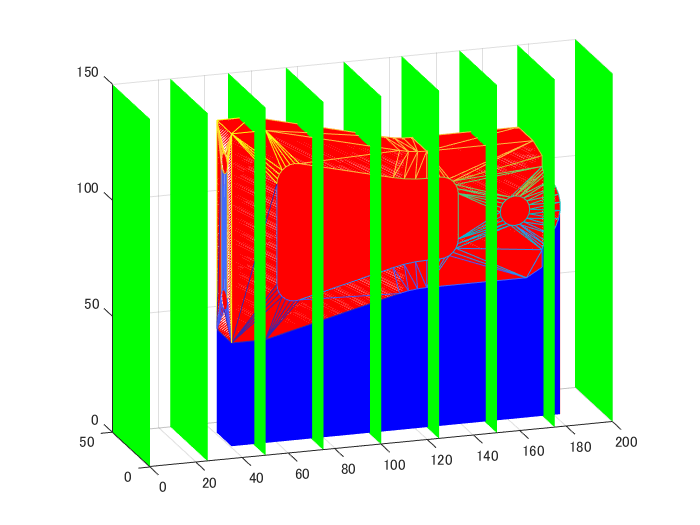

緑色の平面にはさまれた部分の体積を求めます．

2章で説明したパッチの体積の計算では、パッチがxy平面と交わらない場合が望ましいことがわかります。

そのため、2章で読み込んだモデルは、あらかじめz座標の全てが0以上となるように移動してあります。

（モデルの座標空間での位置については次章で述べます。）

各区間の体積を保管する $1\times 200$ の配列 volume を求めることがゴールです．

$1\times 200$ の配列 volume の仕様は以下の通りです．

- volume(1) には x=1 から x=2 の区間における体積を保管します．

- volume(2) には x=2 から x=3 の区間における体積を保管します．

- 
$$\vdots$$


- volume(k) には x=k から x=k+1 の区間における体積を保管します．

- 
$$\vdots$$


- volume(200) には x=200 から x=201 の区間における体積を保管します．

## 新しいラドン変換の求め方

大雑把に説明します．後で詳しく説明します．イメージだけ掴んでください．

頂点リストからパッチを取り出し，頂点を x の昇順に p_xmin, p_xmid, p_xmax とします．

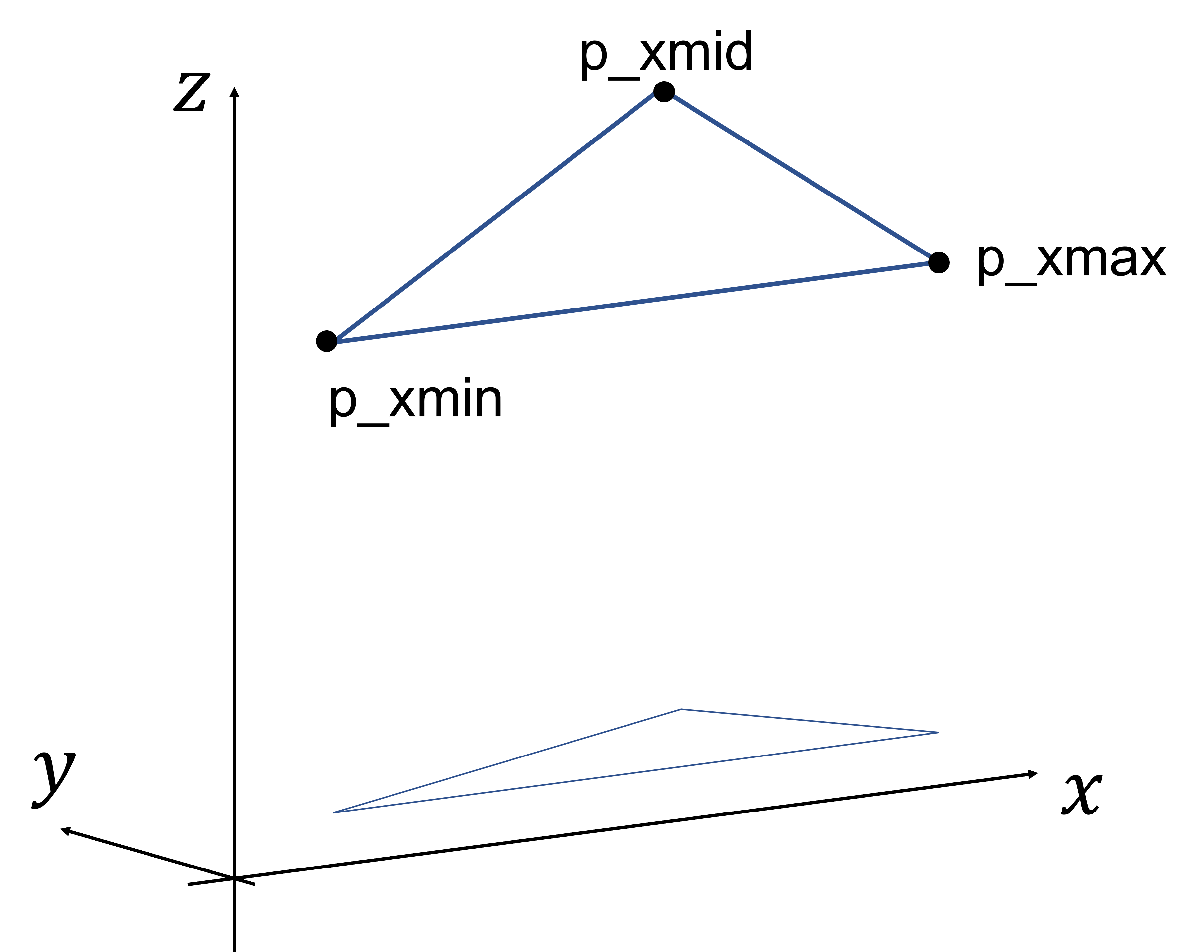

p_xmin の x 座標以下のうち最も大きい整数を開始インデクス start_idx とする．

よって，start_idx = floor(p_xmin(1));

p_xmid の x 座標以下のうち最も大きい整数を終了インデクス end_idx とする．

よって，end_idx = floor(p_xmid(1));

区間ごとに体積を計算するイメージ

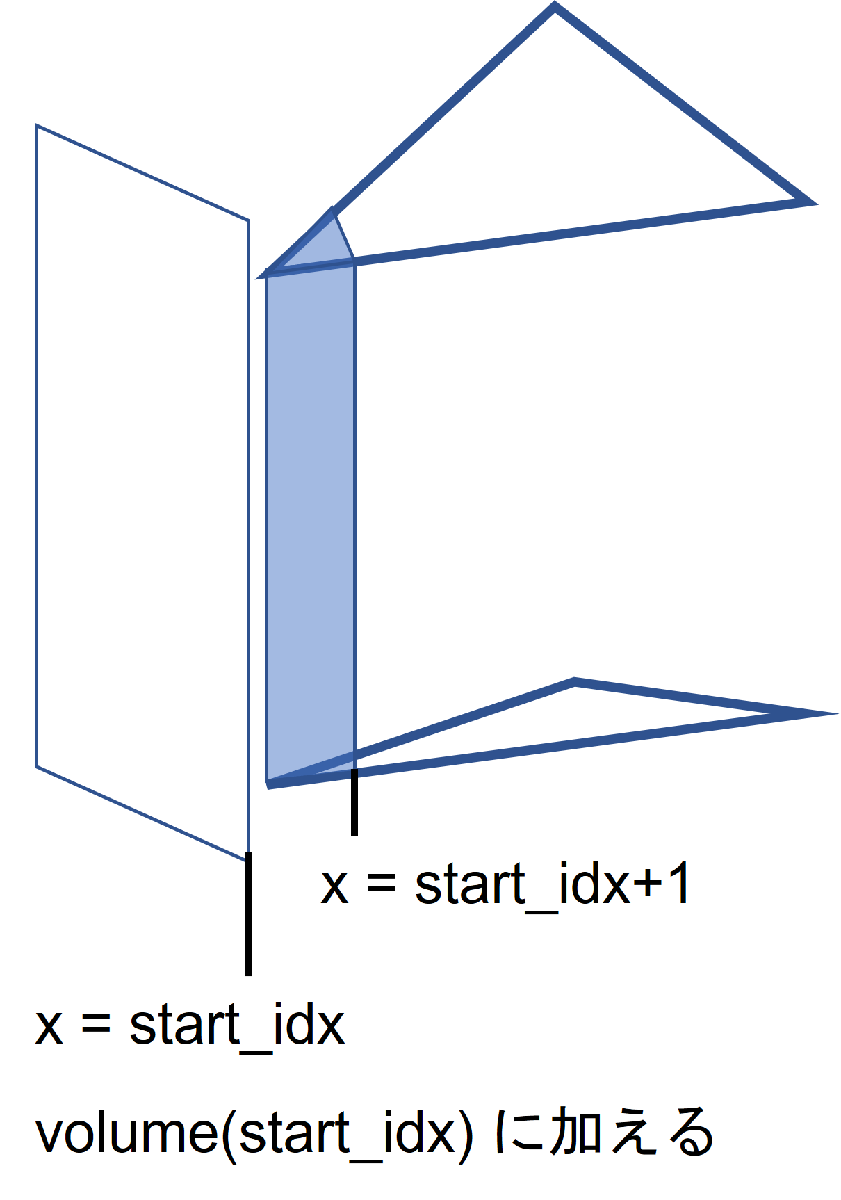

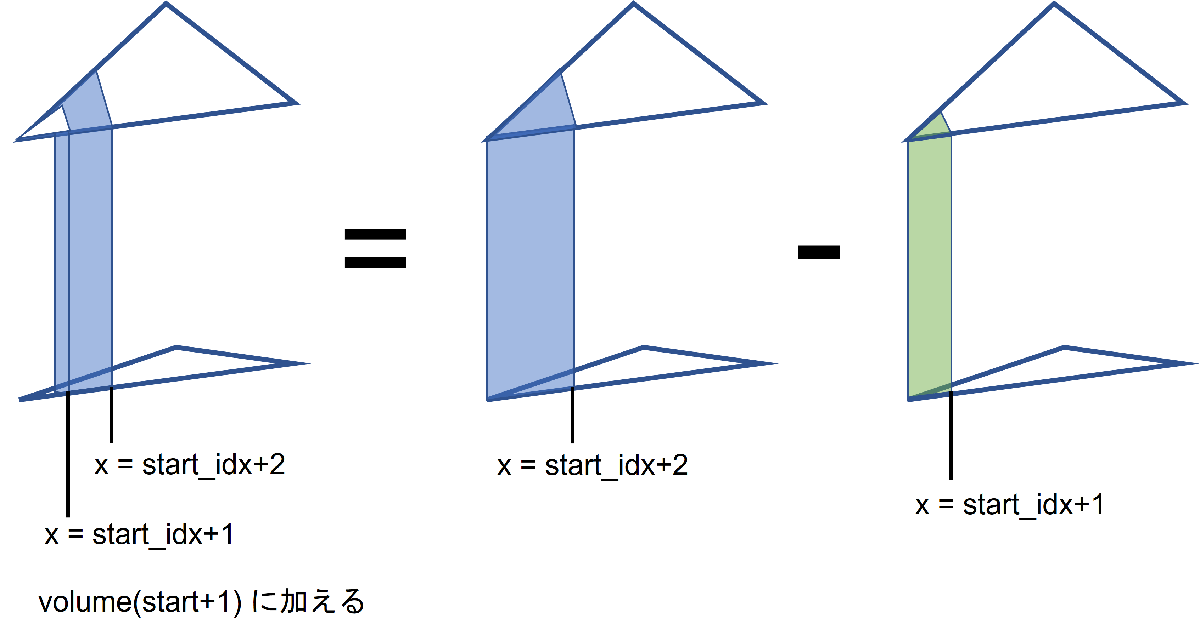

## 
$$\vdots$$


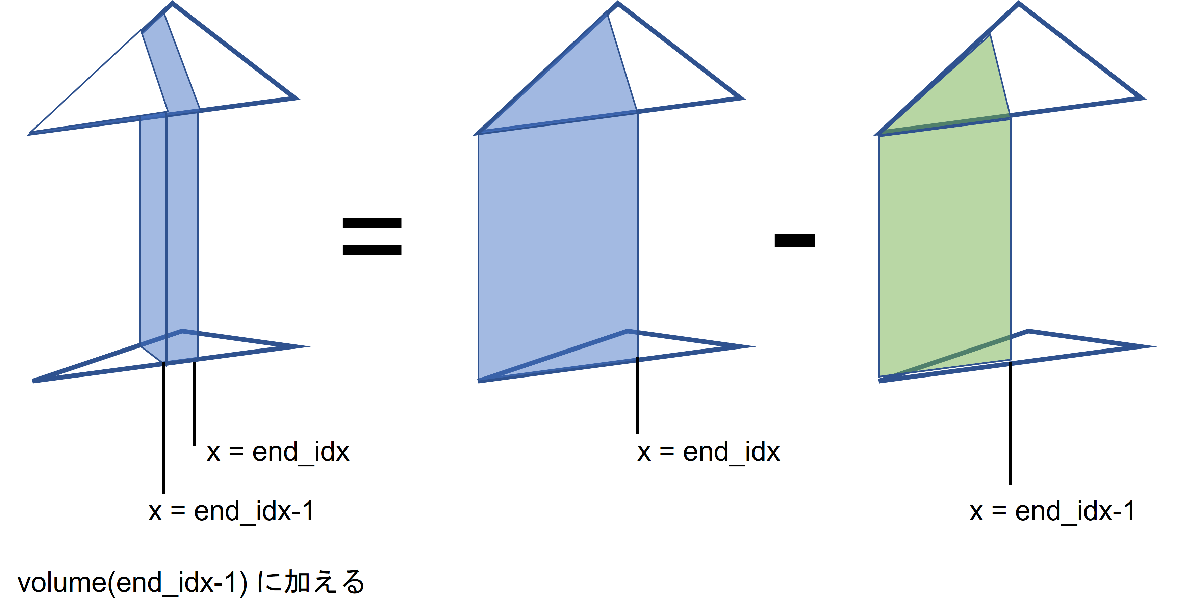

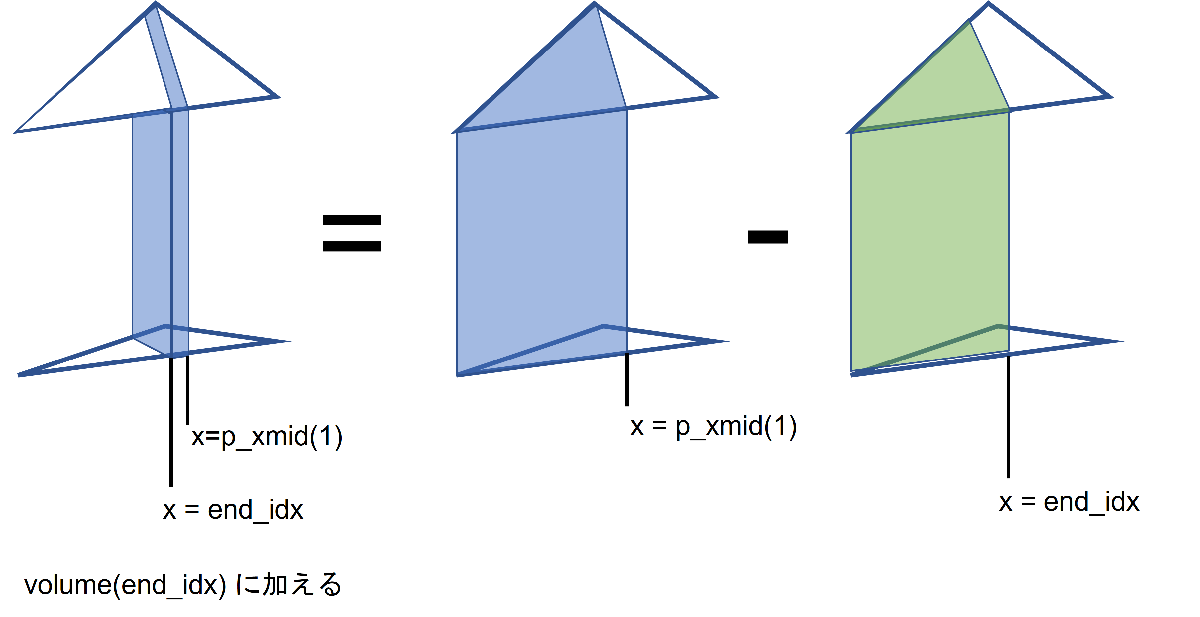

反対側も似たような手順で計算します．

このように，切頭三角柱の体積計算を繰り返すことによって，区間毎の体積を求めることができます．

## 三角形の頂点p1,p2,p3 をx軸の昇順に並べて p_xmin, p_xmid, p_xmax にする．

新しいラドン変換では，三角形の頂点の順序を x軸の昇順に並べ替える必要があります．

具体的には，三角形の頂点が p1, p2, p3 の順番だった時，xの値が大きくなる順番(<)で p_xmin, p_xmid, p_xmax として並べます．

次のコードを実行してみましょう．

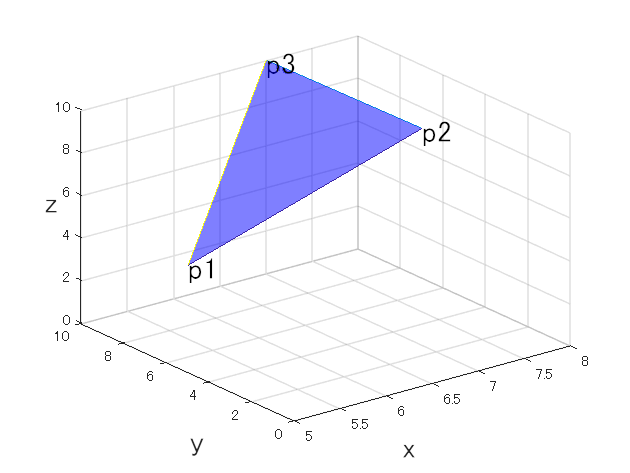

p1 = [5, 5, 5];   %１番目の頂点 p1
p2 = [8, 7, 7];   %２番目の頂点 p2
p3 = [7, 10, 10]; %３番目の頂点 p3

% 三角形を青で表示
figure;
trimesh([1,2,3], [p1(1),p2(1),p3(1)], [p1(2),p2(2),p3(2)], [p1(3),p2(3),p3(3)], FaceColor='b', FaceAlpha=0.5);
text(p1(1), p1(2), p1(3), 'p1', FontSize=20);
text(p2(1), p2(2), p2(3), 'p2', FontSize=20);
text(p3(1), p3(2), p3(3), 'p3', FontSize=20);
xlabel('x', FontSize=20);
ylabel('y', FontSize=20);
zlabel('z', FontSize=20, Rotation=0);
ylim([0,10]);
zlim([0,10]);

このように，p1 p2 p3 がｘ軸に昇順にになっていません．

頂点をxの昇順に並べ替えるには，matlab の sortrows() を使うといいと思います．

% sortrows の使い方例
A = [
    30, 60, 80;
    20, 40, 70;
    10, 50, 90
    ]

A =     30    60    80
    20    40    70
    10    50    90



% A を 1 列目の昇順 "ascend" で並べ替え．そして，B に代入
B = sortrows(A, 1, "ascend")

B =     10    50    90
    20    40    70
    30    60    80



% A を 2 列目の昇順 "ascend" で並べ替え．そして，C に代入
C = sortrows(A, 2, "ascend")

C =     20    40    70
    10    50    90
    30    60    80


### 課題：以上の sortrows() を使って 三角形の頂点p1,p2,p3 をx軸の昇順に並べて p_xmin, p_xmid, p_xmax にましょう．

P = [
    p1;
    p2;
    p3;
    ]

P =      5     5     5
     8     7     7
     7    10    10


P_sorted_by_x = P;


% ↓ sortrows() の括弧内を正しく書きましょう．
P_sorted_by_x = sortrows();

P_sorted_by_x =      5     5     5
     7    10    10
     8     7     7


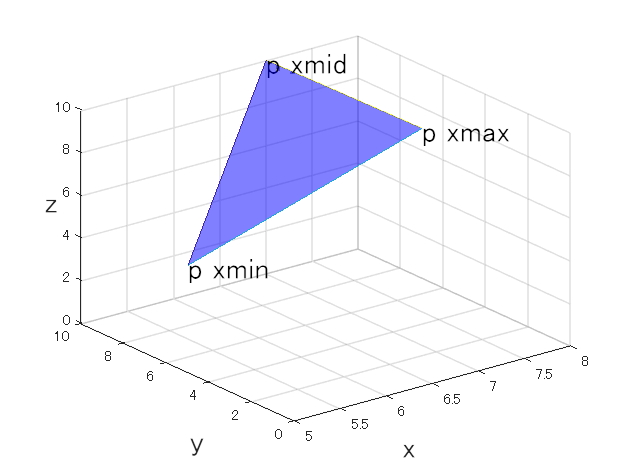


p_xmin = P_sorted_by_x(1,:);
p_xmid = P_sorted_by_x(2,:);
p_xmax = P_sorted_by_x(3,:);


% 三角形を青で表示
figure;
trimesh([1,2,3], P_sorted_by_x(:,1), P_sorted_by_x(:,2), P_sorted_by_x(:,3), FaceColor='b', FaceAlpha=0.5);
text(p_xmin(1), p_xmin(2), p_xmin(3), 'p xmin', FontSize=20);
text(p_xmid(1), p_xmid(2), p_xmid(3), 'p xmid', FontSize=20);
text(p_xmax(1), p_xmax(2), p_xmax(3), 'p xmax', FontSize=20);
xlabel('x', FontSize=20);
ylabel('y', FontSize=20);
zlabel('z', FontSize=20, Rotation=0);
ylim([0,10]);
zlim([0,10]);
hold on;
view(3);

頂点がx軸の方向において p_xmin, p_xmid, p_xmax の順番に表示されていれば成功です．

## 三角形の辺と平面の交点を求める．（昔のラドン変換の時と全く同じです．）

新しいラドン変換を行うためには下の図のように，三角形の辺と平面の交点を求める必要があります．

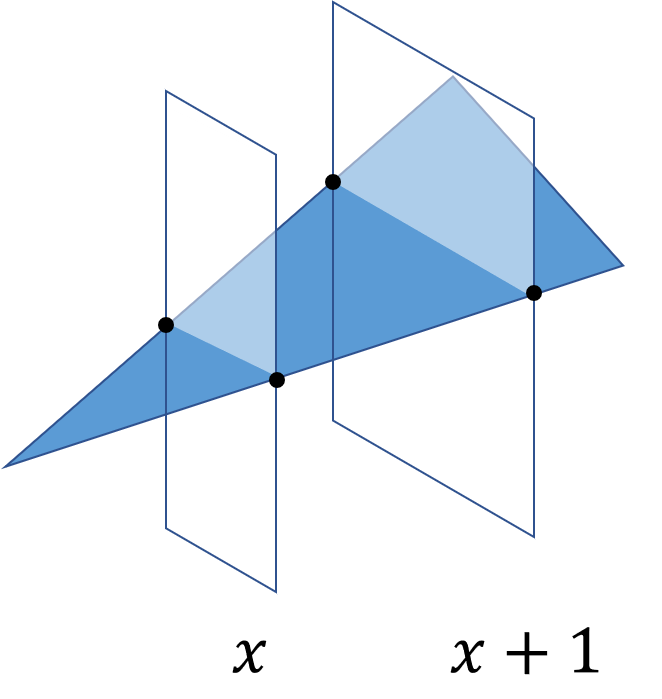

以下のコードで交点の座標を計算します。

関数 slice_edge は、ファイル slice_edge.m で定義されていますが、まだ関数の中身が書かれていません。

正しく計算できるように、関数の中身を書き換えてください。

#### 課題：slice_edge.m を作成して，先ほどの三角形と平面 x = slice_X (今回は6) との交点を求めましょう．

p1 = [5, 5, 5];   %１番目の頂点 p1
p2 = [8, 7, 7];   %２番目の頂点 p2
p3 = [7, 10, 10]; %３番目の頂点 p3

P = [
    p1;
    p2;
    p3;
    ];

% ↓ 手作業で並べ替え．今後は sortrows() を使いましょう．
p_xmin = p1;
p_xmid = p3;
p_xmax = p2;



% 断面
slice_X = 6;
text(slice_X, 0, 5, sprintf('sliceX=%d', slice_X), FontSize=20)
% 断面を緑で表示
patch("Faces", [1,2,3,4], ...
 "Vertices", ...
 [slice_X, 0, 0; ...
 slice_X, 0, 10; ...
 slice_X, 10, 10; ...
 slice_X, 10, 0], ...
 FaceColor="g", FaceAlpha=0.5);
xlabel('x', FontSize=20);
ylabel('y', FontSize=20);
zlabel('z', FontSize=20, Rotation=0);


% slice_edge.m ファイルを作成しましょう，
% ↓ 辺 p_xmin -> p_xmax と平面 slice_X=6 との交点 q_xmin_xmax を求める．
q_xmin_xmax = slice_edge(p_xmin, p_xmax, slice_X)

q_xmin_xmax =     6.0000    5.6667    5.6667



% ↓ 辺 p_xmin -> p_xmid と平面 slice_X=6 との交点 q_xmin_xmid を求める．
q_xmin_mid = slice_edge(p_xmin, p_xmid, slice_X)

q_xmin_mid =     6.0000    7.5000    7.5000


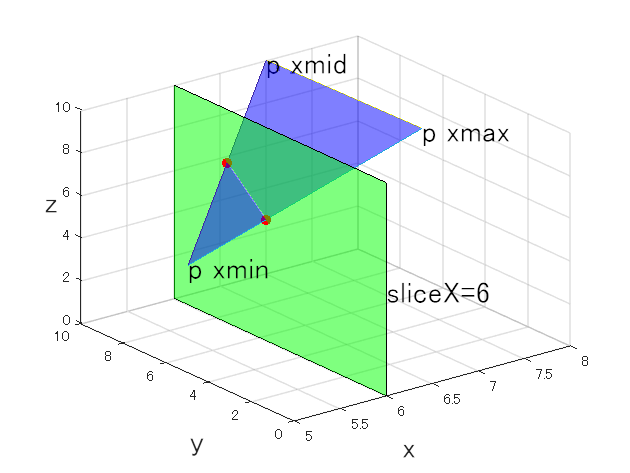


% 交点を表示
plot3(q_xmin_xmax(1), q_xmin_xmax(2), q_xmin_xmax(3), '.', MarkerSize=20, Color='r');
plot3(q_xmin_mid(1), q_xmin_mid(2), q_xmin_mid(3), '.', MarkerSize=20, Color='r');
view(3);

緑の平面と青の三角形の辺と交点に赤点があれば成功です．

## １つの切頭三角柱の体積変化を求める．

#### 課題：x=5からx=6の区間おける切頭三角柱の体積 volume56 を求めましょう．

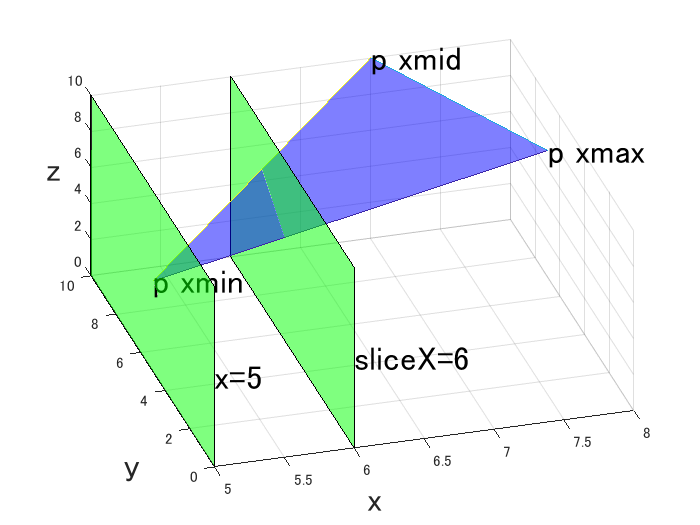

% 課題
slice_X = 6;
% ↓ calc_volume() の括弧内を正しく書き換えましょう．% 交点は slice_edge() 求めることができます．
% volume56 = calc_volume(); 
volume56 = 0 % ← calc_volume(), slice_edge(), p_xmin, p_xmid, p_xmax, slice_X を使って求めましょう．

volume56 = 0

#### 課題：x=6からx=7の区間おける切頭三角柱の体積 volume67 を求めましょう．

volume67 は p_xmin と x=7 の間に挟まれた切頭三角柱の体積から volume56 を引くことで求められます．

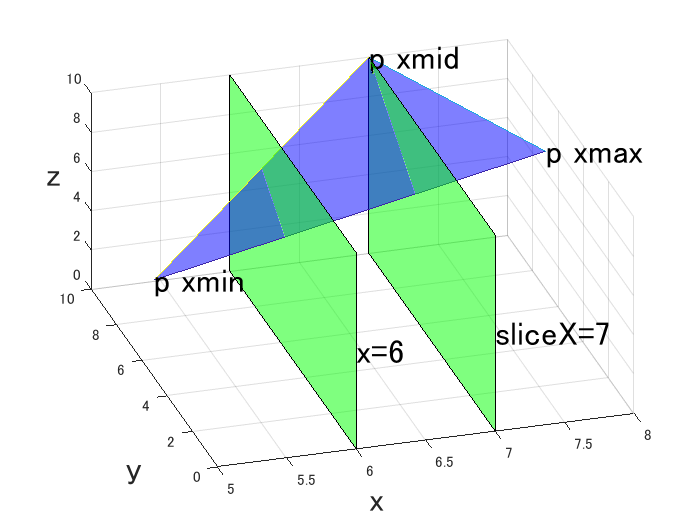　　　　

% 課題
slice_X = 7;
% ↓ calc_volume() の括弧内を正しく書き換えましょう．% 交点は slice_edge() 求めることができます．
% volume67 = calc_volume(); 
volume67 = 0 % ← calc_volume(), slice_edge(), p_xmin, p_xmid, p_xmax, slice_X を使って求めましょう．

volume67 = 0

#### 課題：x=8からx=7の区間おける切頭三角柱の体積 volume87 を求めましょう．

今回は，p_xmax と p_xmid が平面内にあるので，単純に切頭三角柱の体積を求めましょう．

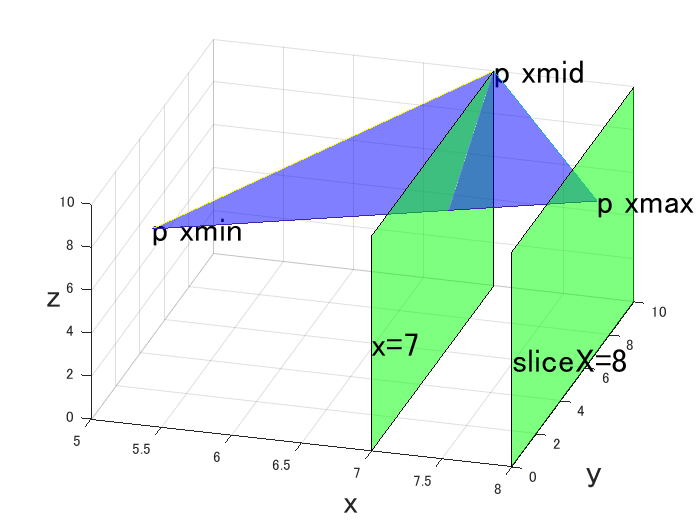

% 課題
slice_X = 7;
% ↓ calc_volume() の括弧内を正しく書き換えましょう．% 交点は slice_edge() 求めることができます．
% volume87 = calc_volume(); 
volume87 = 0 % ← calc_volume(), slice_edge(), p_xmin, p_xmid, p_xmax, slice_X を使って求めましょう．

volume87 = 0

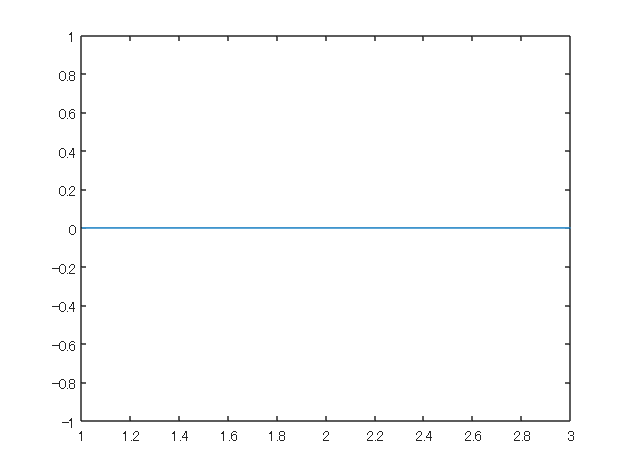


figure;
plot([volume56, volume67, volume87])

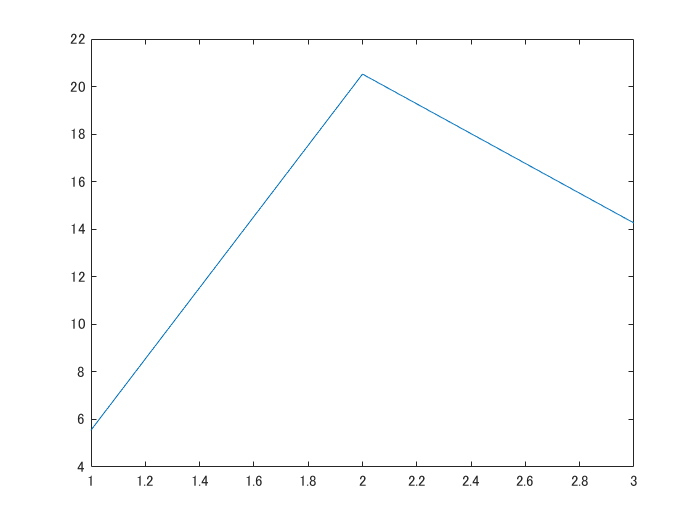

同じようなグラフが出来ればokです．

テストコード

assert( abs(volume56 + volume67 + volume87 - calc_volume(p_xmin, p_xmid, p_xmax)) < 1e-5 )

アサーションに失敗しました。

## for文 を利用して１つの切頭三角柱の体積変化を求める．

先ほどの三角形は x が 5~8 の間に収まる小さい三角形でした．

しかし，大きい三角形も存在します．

したがって，先ほどの計算を for で繰り返し処理をする必要があります．

大きい三角形を生成しますので，以下のコードを実行してください．

clear;

p1 = [20.4, 50, 50];   %１番目の頂点 p1
p2 = [80.3, 60, 70];   %２番目の頂点 p2
p3 = [59.8, 100, 90]; %３番目の頂点 p3

P = [
    p1;
    p2;
    p3;
    ];
P_sorted_by_x = sortrows(P, 1,"ascend")

P_sorted_by_x =    20.4000   50.0000   50.0000
   59.8000  100.0000   90.0000
   80.3000   60.0000   70.0000


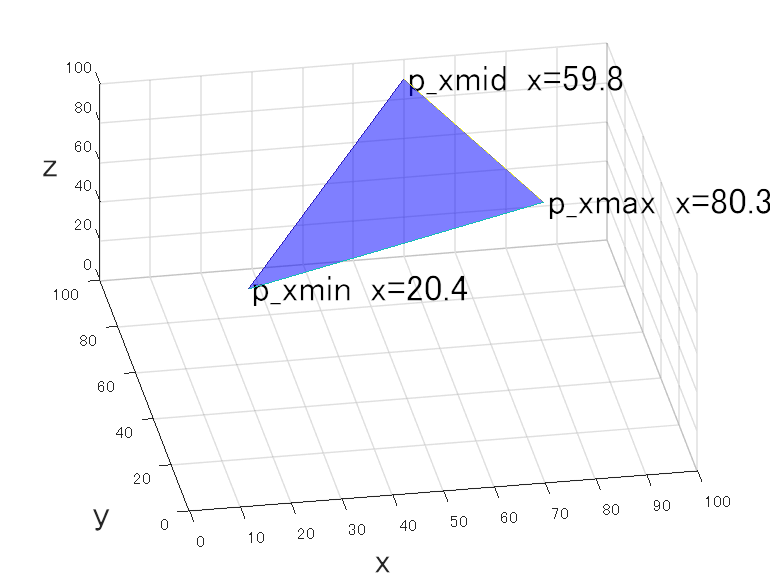


p_xmin = P_sorted_by_x(1,:);
p_xmid = P_sorted_by_x(2,:);
p_xmax = P_sorted_by_x(3,:);


% 三角形を青で表示
figure;
trimesh([1,2,3], P_sorted_by_x(:,1), P_sorted_by_x(:,2), P_sorted_by_x(:,3), FaceColor='b', FaceAlpha=0.5);
text(p_xmin(1), p_xmin(2), p_xmin(3), 'p\_xmin x=20.4', FontSize=20);
text(p_xmid(1), p_xmid(2), p_xmid(3), 'p\_xmid x=59.8', FontSize=20);
text(p_xmax(1), p_xmax(2), p_xmax(3), 'p\_xmax x=80.3', FontSize=20);

%{
% 断面
slice_X = 20;
text(slice_X, 0, 50, sprintf('sliceX=%d', slice_X), FontSize=20)
% 断面を緑で表示
patch("Faces", [1,2,3,4], ...
 "Vertices", ...
 [slice_X, 0, 0; ...
 slice_X, 0, 100; ...
 slice_X, 100, 100; ...
 slice_X, 100, 0], ...
 FaceColor="g", FaceAlpha=0.5);

% 断面
slice_X = 80;
text(slice_X, 0, 50, sprintf('sliceX=%d', slice_X), FontSize=20)
% 断面を緑で表示
patch("Faces", [1,2,3,4], ...
 "Vertices", ...
 [slice_X, 0, 0; ...
 slice_X, 0, 100; ...
 slice_X, 100, 100; ...
 slice_X, 100, 0], ...
 FaceColor="g", FaceAlpha=0.5);
%}

xlabel('x', FontSize=20);
ylabel('y', FontSize=20);
zlabel('z', FontSize=20, Rotation=0);
xlim([0,100]);
ylim([0,100]);
zlim([0,100]);
view([-10, 50]);

p_xmin のx座標は 20.4，p_xmid の x 座標は 59.8，p_max の x 座標は 80.3 です．

### 課題：上図の三角形の体積を配列volumeとして求めてください．volume の仕様は以下の通りです．

            volume の大きさは 1 $\times $ 100 です．

- volume(1) には x=1 から x=2 の区間の体積を保管します．

- volume(2) には x=2 から x=3 の区間の体積を保管します．

- 
$$\vdots$$


- volume(k) には x=k から x=k+1 の区間の体積を保管します．

- 
$$\vdots$$


- volume(100) には x=100 から x=101 の区間の体積を保管します．

変数，old_volume を1つ前 (old) の体積．変数 current_volume を現在 (current) の体積として使いましょう．

#### 課題１：最初に p_xmin から p_xmid までの体積を求めましょう．

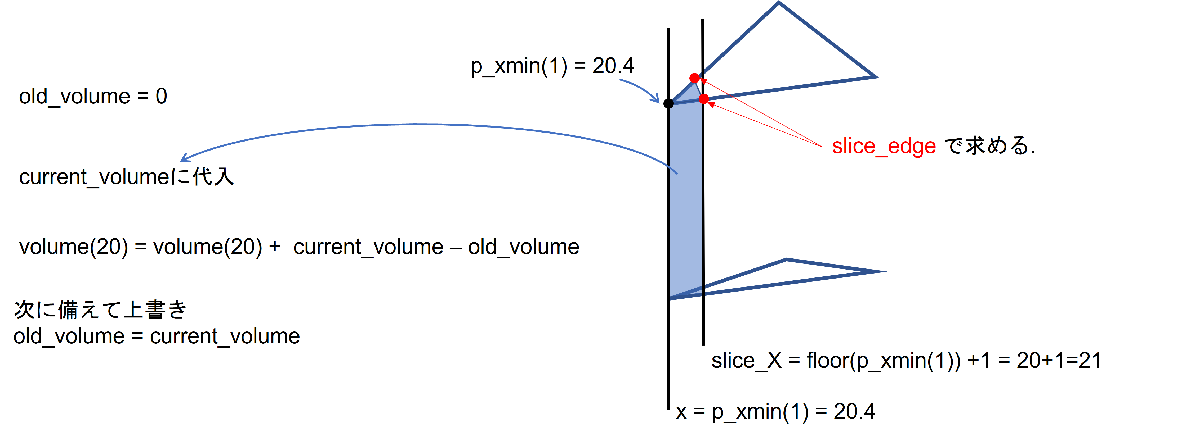

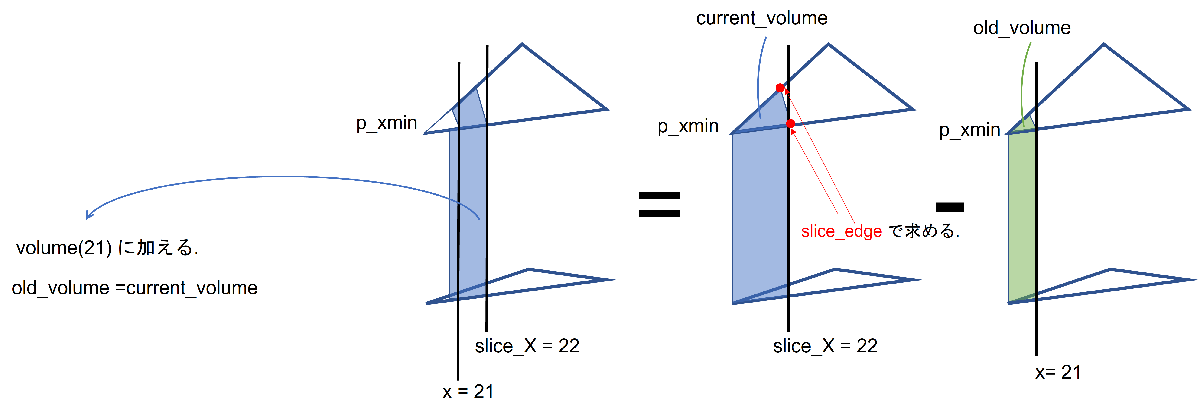

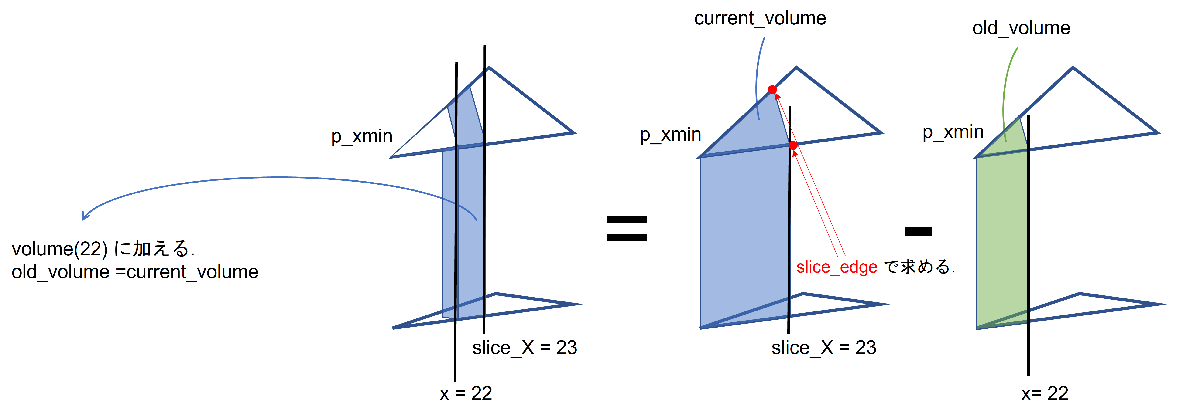

## 
$$\vdots$$


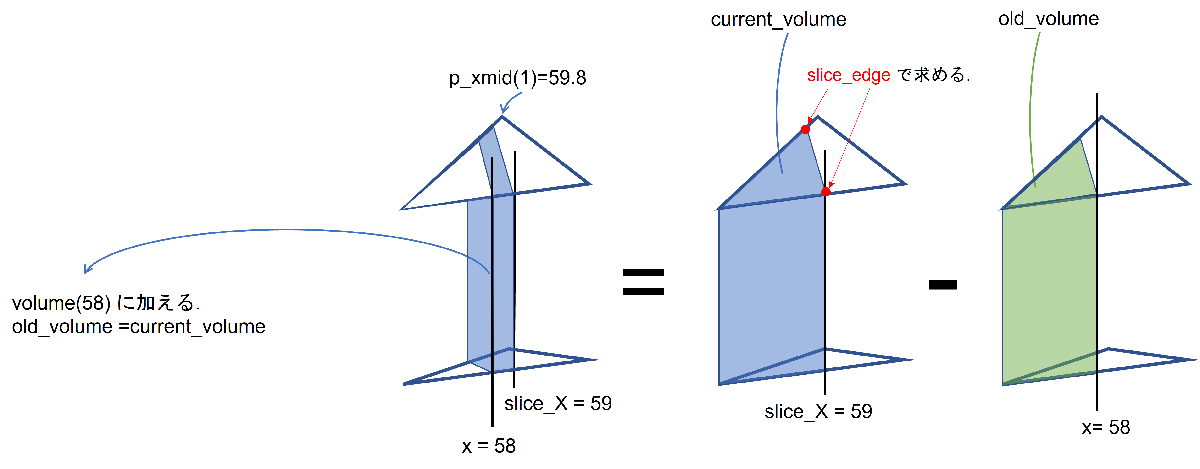

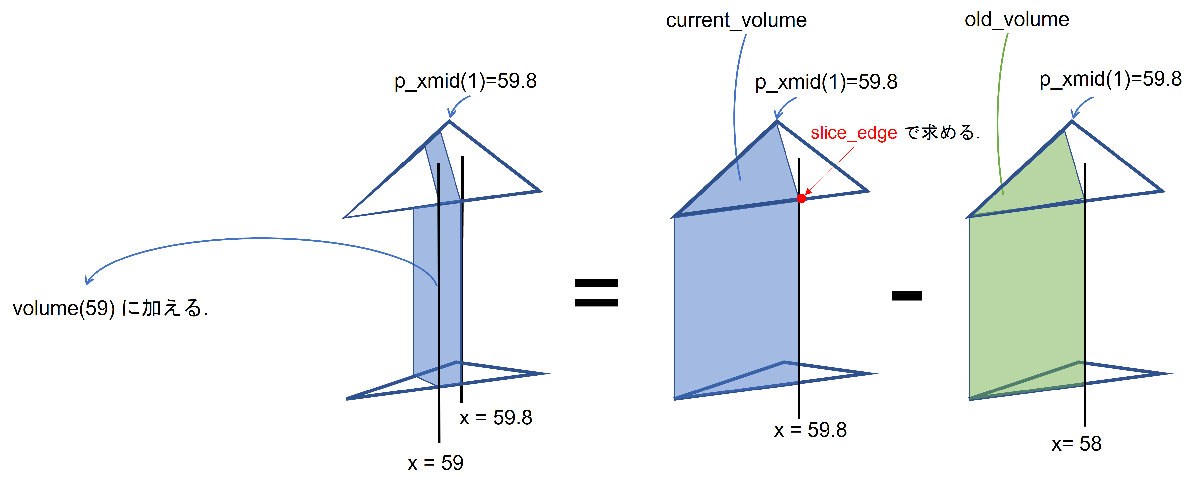

% 課題１

volume = zeros(1, 100);

% p_xmin から p_xmid まで間の体積を格納する配列 volume を求めましょう．

old_volume = 0; % 1つ前 (old) の体積
current_volume = 0; % 現在 (current) の体積

for slice_X = 1:100 % ← p_xmin(1), p_xmid(1) を使って書き換えてください．
    current_volume = 0; % ← calc_volume(), slice_edge(), p_xmin, p_xmid, p_xmax, slice_X を使って書き換えてください．
    volume(1) = volume(1) + 0; % ← current_volume, old_volume, slice_X を使って書き換えてください．
    old_volume = current_volume;
end


#### 課題２： p_xmax から p_xmid までの区間 x = 60 ~ 80 における体積 volume(79) ~ volume(60) を求めましょう．

今度は右から攻めます．つまり，volume(79), volume(78), volume(77), ..., volume(60) の順で求めます．

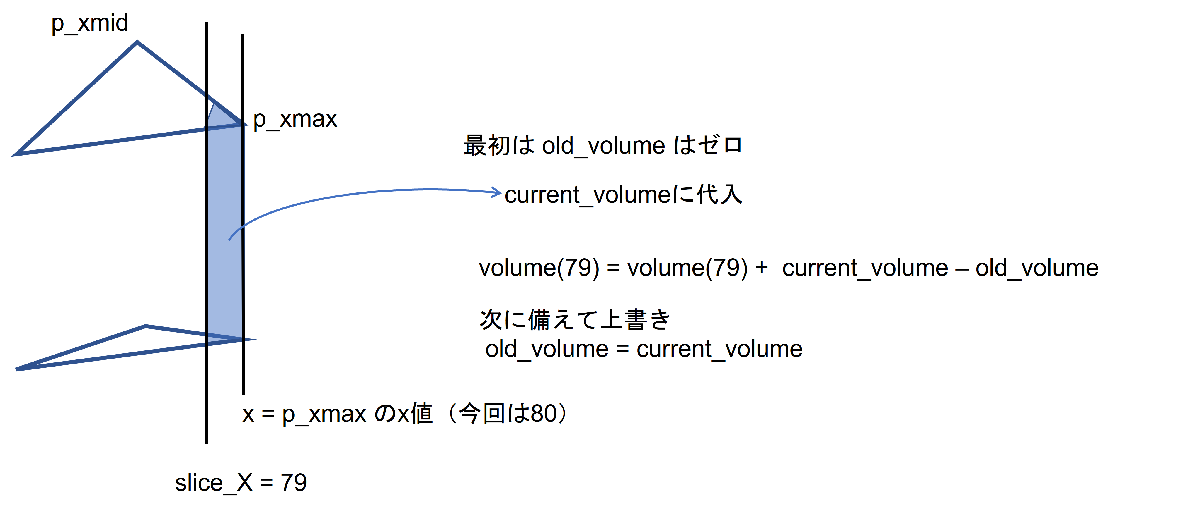

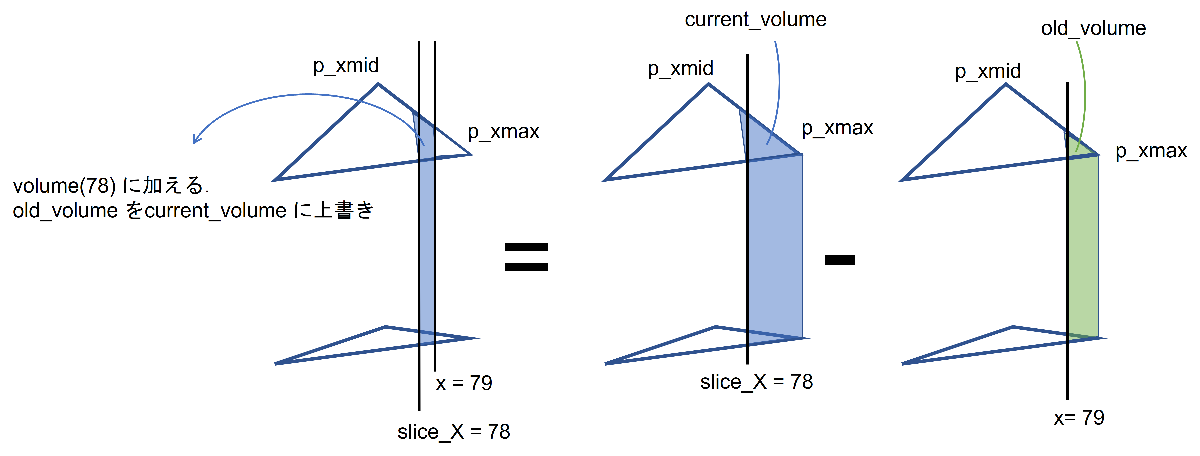

## 
$$\vdots$$


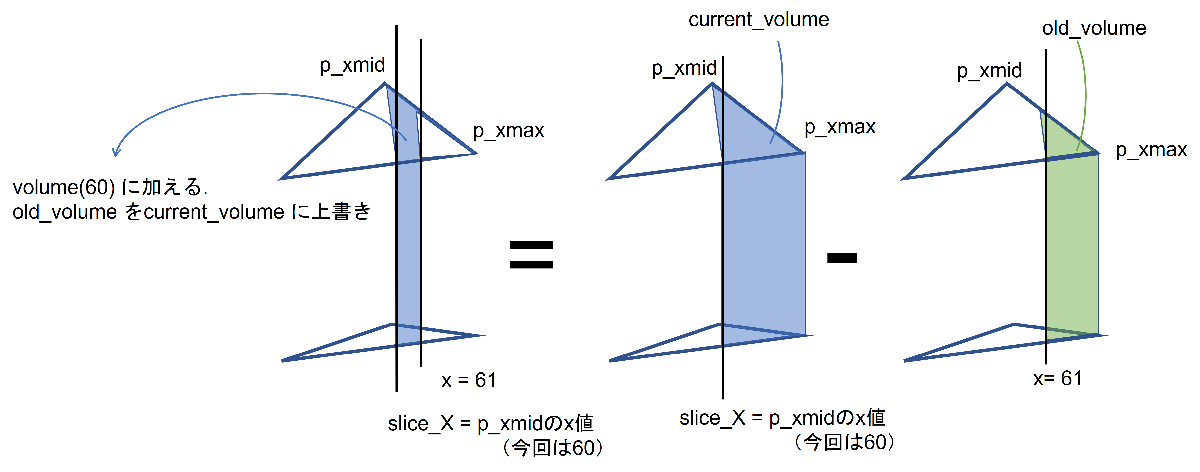

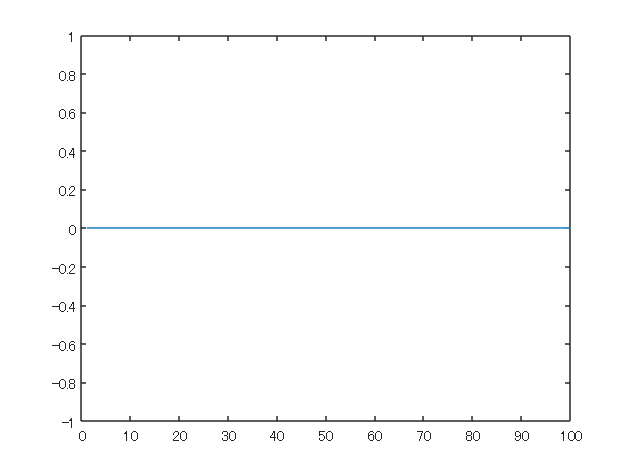

% 課題２
% p_xmax から p_xmid までの区間 x = 80 ~ 60 における体積 volume(79) ~ volume(60) を求めましょう．

old_volume = 0; % 1つ前 (old) の体積
current_volume = 0; % 現在 (current) の体積

% for 文を降順 100, 99, 98, ..., 1 とするには for slice_X = 100:-1:1
% :-1: は差分がマイナス１という意味．
for slice_X = 100:-1:1 % ← p_xmax(1), p_xmid(1) を使って書き換えてください．
    current_volume = 0; % ← calc_volume(), slice_edge(), p_xmin, p_xmid, p_xmax, slice_X を使って書き換えてください．
    volume(1) = volume(1) + 0; % ← current_volume, old_volume, slice_X を使って書き換えてください．
    old_volume = current_volume;
end


figure;
plot(volume);

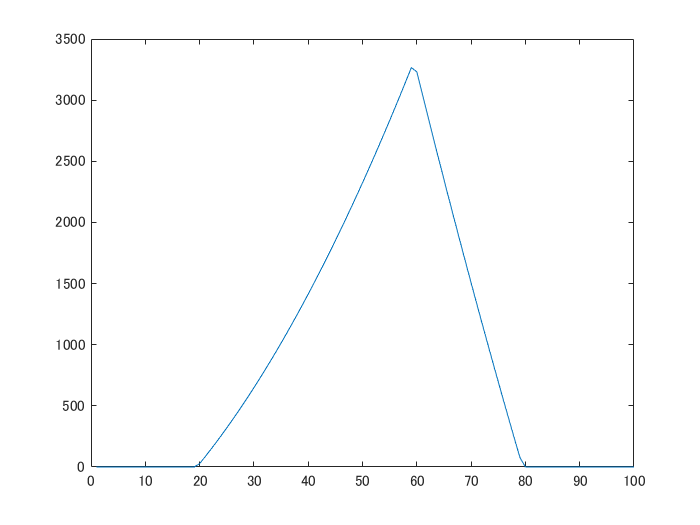このようなグラフが表示されていればokです．

テストコード

assert(abs(sum(volume) - calc_volume(p_xmin, p_xmid, p_xmax)) < 1e-5);

アサーションに失敗しました。

## ややこしい三角形に対応できるようにする．

#### 新しいラドン変換は，今から説明する内容が非常にややこしいです．

先ほどの三角形は x=20 で始まり，x=80で終了するという，両端が整数であるという都合のよい三角形でした．

しかし，実際は x=20.4 で始まり，x=79.8 で終了するような三角形も存在します．

具体的に問題となる三角形を表示しますので，以下のコードを実行してください．

clear;

p1 = [20.4, 50, 50];   %１番目の頂点 p1
p2 = [80.3, 60, 70];   %２番目の頂点 p2
p3 = [59.8, 100, 90]; %３番目の頂点 p3

P = [
    p1;
    p2;
    p3;
    ];
P_sorted_by_x = sortrows(P, 1,"ascend")

P_sorted_by_x =    20.4000   50.0000   50.0000
   59.8000  100.0000   90.0000
   80.3000   60.0000   70.0000


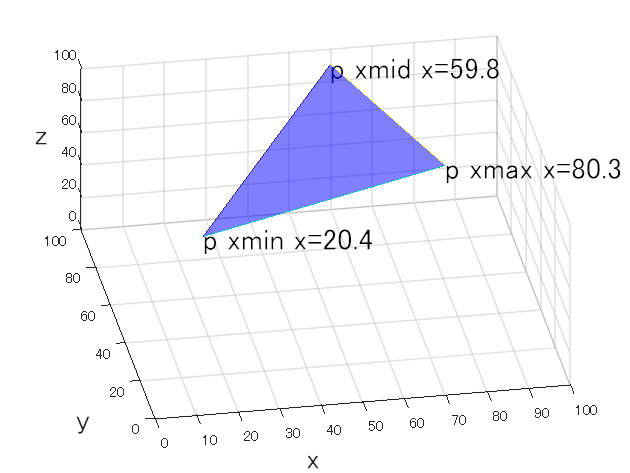


p_xmin = P_sorted_by_x(1,:);
p_xmid = P_sorted_by_x(2,:);
p_xmax = P_sorted_by_x(3,:);


% 三角形を青で表示
figure;
trimesh([1,2,3], P_sorted_by_x(:,1), P_sorted_by_x(:,2), P_sorted_by_x(:,3), FaceColor='b', FaceAlpha=0.5);
text(p_xmin(1), p_xmin(2), p_xmin(3), 'p xmin x=20.4', FontSize=20);
text(p_xmid(1), p_xmid(2), p_xmid(3), 'p xmid x=59.8', FontSize=20);
text(p_xmax(1), p_xmax(2), p_xmax(3), 'p xmax x=80.3', FontSize=20);
xlabel('x', FontSize=20);
ylabel('y', FontSize=20);
zlabel('z', FontSize=20, Rotation=0);
xlim([0,100]);
ylim([0,100]);
zlim([0,100]);
view([-10, 50]);

上のような三角形の場合，

そのような，場合に対応できるように先ほどのコードを変更しましょう．

以下に，先ほどの課題の解答を一部載せます．

% 解答
volume = zeros(1, 100);

% p_xmin から p_xmid までの区間 x = 20 ~ 60 における体積 volume(20) ~ volume(59) を求めましょう．

old_volume = 0; % 1つ前 (old) の体積
current_volume = 0; % 現在 (current) の体積

for slice_X = p_xmin(1)+1:p_xmid(1) % ← p_xmin(1), p_xmid(1) を使って書き換えてください．
    current_volume = 0; % ← calc_volume(), slice_edge(), p_xmin, p_xmid, p_xmax, slice_X を使って書き換えてください．
    volume(1) = volume(1) + 0; % ← current_volume, old_volume, slice_X を使って書き換えてください．
    old_volume = current_volume;
end

% p_xmin から p_xmid までの区間 x = 20 ~ 60 における体積 volume(20) ~ volume(59) を求めましょう．

old_volume = 0; % 1つ前 (old) の体積
current_volume = 0; % 現在 (current) の体積

% for 文を降順 100, 99, 98, ..., 1 とするには for slice_X = 100:-1:1
% :-1: は差分がマイナス１という意味．
for slice_X = p_xmax(1)-1:-1:p_xmid(1) % ← p_xmax(1), p_xmid(1) を使って書き換えてください．
    current_volume = 0; % ← calc_volume(), slice_edge(), p_xmin, p_xmid, p_xmax, slice_X を使って書き換えてください．
    volume(1) = volume(1) + 0; % ← current_volume, old_volume, slice_X を使って書き換えてください．
    old_volume = current_volume;
end

#### 最初から１つ目の for 文 

#### for slice_X = p_xmin(1):p_xmid(1)    に着目してください．

もし，仮に， x = 20.4 で始まり，三角形の p_xmid が 59.8 のような三角形の場合，

p_xmin(1) = 20.4,  p_xmid(1) = 59.8 となるので，

slice_X は 20.4, 21.4, 22.4, ... のように，整数ではなくなってしまいます．

これではいけないので，slice_X が 21, 20, 22, ... , 59 となるようにしましょう．

したがって，slice_X が p_xmin(1) の以上の最小の整数から１つづ増加し，p_xmid(1) 以下の最大の整数で終了するようにしましょう．

matlab には floor 関数が用意されています．floor(a) のように使うと，a 以下の最大整数を計算できます．

また，matlab には ceil 関数が用意されています．ceil(a) のように使うと，a 以上の最小整数を計算できます．

しかし，これだけでは，x = 59 ~ 59.8 の間が計算されないので，for 文が終了したら，x = 59 ~ 59.8 の間の計算をしましょう．

したがって，slice_X = p_xmid(1) (今回は59.8) として計算し，volume(floor(p_xmid(1)) （今回は volume(59)）に加えましょう．

#### 次に，２つの目の for 文

#### for slice_X = p_xmax(1)-1:-1:p_xmid(1) に着目してください．

こちらも同様に，もし仮に，p_xmax(1) = 80.3,  p_xmid(1) = 59.8 の場合，

slice_X は 80.3, 79.3, 78.3,  ... のように，整数ではなくなってしまいます．

これではいけないので，slice_X が 80, 79, 78, ... , 60 となるようにしましょう．

したがって，slice_X が p_xmax(1) の以下の最大の整数から１つづ減少し，p_xmid(1) 以上の最小の整数で終了するようにしましょう．

しかし，これだけでは同様に，x = 60 ~ 59.8 の間が計算されないので， for 文が終了したら，x = 60 ~ 59.8 の間の計算をしましょう．

したがって，slice_X = p_xmid(1) (今回は59.8) として計算し，volume(floor(p_xmid(1)) （今回は volume(59)）に加えましょう

これらを踏まえて次の課題に取り組んでください．

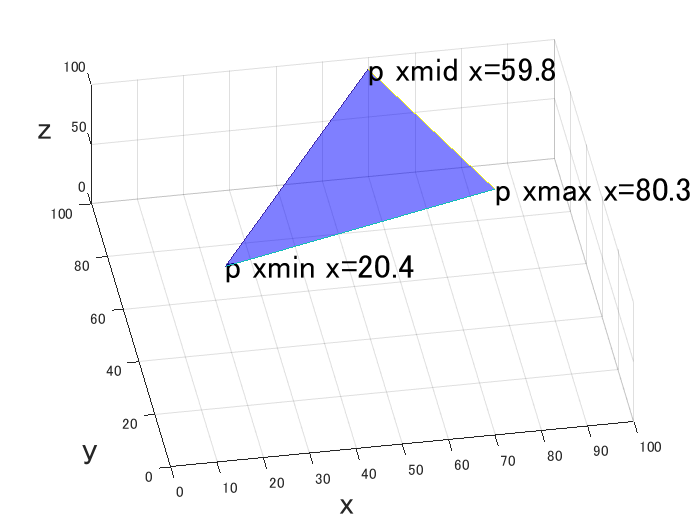

### 課題：上図の三角形の体積を配列volumeとして求めてください．volume の仕様は以下の通りです．

            volume の大きさは 1 $\times $ 100 です．

- volume(1) には x=1 から x=2 の区間における体積を保管します．

- volume(2) には x=2 から x=3 の区間における体積を保管します．

- 
$$\vdots$$


- volume(k) には x=k から x=k+1 の区間における体積を保管します．

- 
$$\vdots$$


- volume(100) には x=100 から x=101 の区間における体積を保管します．

%課題

clear;

p1 = [20.4, 50, 50];   %１番目の頂点 p1
p2 = [80.3, 60, 70];   %２番目の頂点 p2
p3 = [59.8, 100, 90]; %３番目の頂点 p3

P = [
    p1;
    p2;
    p3;
    ];
P_sorted_by_x = sortrows(P, 1,"ascend")

p_xmin = P_sorted_by_x(1,:);
p_xmid = P_sorted_by_x(2,:);
p_xmax = P_sorted_by_x(3,:);

volume = zeros(1, 100);

% p_xmin から p_xmid までの区間 x = 20 ~ 60 における体積 volume(20) ~ volume(59) を求めましょう．

old_volume = 0; % 1つ前 (old) の体積
current_volume = 0; % 現在 (current) の体積

%%%%%%%%%%%%%%　↓　正しく書きましょう %%%%%%%%%%%%%%%%%%%
for slice_X = p_xmin(1)+1:p_xmid(1)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    current_volume = 0; % ← calc_volume(), slice_edge(), p_xmin, p_xmid, p_xmax, slice_X を使って書き換えてください．
    volume(1) = volume(1) + 0; % ← current_volume, old_volume, slice_X を使って書き換えてください．
    old_volume = current_volume;
end

%%%%%%%　↓　x = 59 ~ 59.8 の計算をしましょう．　%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



% p_xmax から p_xmid までの区間 x = 80 ~ 59.8 における体積 volume(79) ~ volume(59) を求めましょう．

old_volume = 0; % 1つ前 (old) の体積
current_volume = 0; % 現在 (current) の体積

% for 文を降順 100, 99, 98, ..., 1 とするには for slice_X = 100:-1:1
% :-1: は差分がマイナス１という意味．

%%%%%%%%%%%%%%　↓　正しく書きましょう %%%%%%%%%%%%%%%%%%
for slice_X = p_xmax(1):-1:p_xmid(1) 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    current_volume = 0; % ← calc_volume(), slice_edge(), p_xmin, p_xmid, p_xmax, slice_X を使って書き換えてください．
    volume(1) = volume(1) + 0; % ← current_volume, old_volume, slice_X を使って書き換えてください．
    old_volume = current_volume;
end

%%%%%%%　↓　x = 60 ~ 59.8 の計算をしましょう．　%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## 新しいラドン変換を完成させよう．

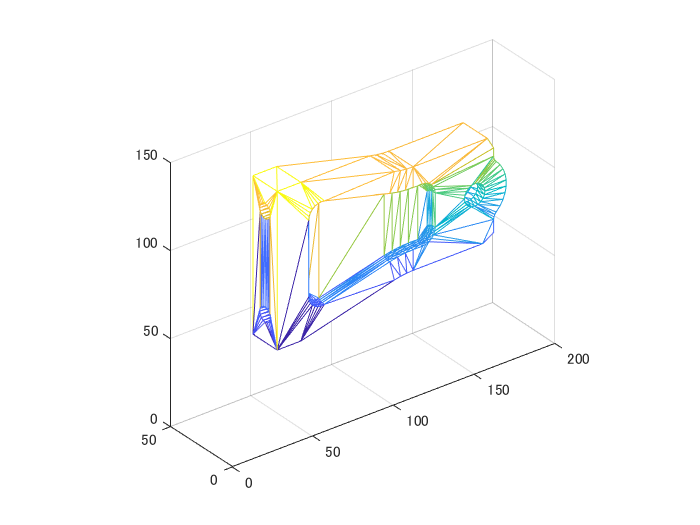

### 課題：上図の3D CAD モデルの体積を配列volumeとして求めてください．volume の仕様は以下の通りです．

            volume の大きさは 1 $\times $ 200 です．

- volume(1) には x=1 から x=2 の区間における体積を保管します．

- volume(2) には x=2 から x=3 の区間における体積を保管します．

- 
$$\vdots$$


- volume(k) には x=k から x=k+1 の区間における体積を保管します．

- 
$$\vdots$$


- volume(200) には x=200 から x=201 の区間における体積を保管します．

#### 以下のコードを完成させてください．


clear;

TR = stlread('sampleModel.stl');

p = TR.Points;
c = TR.ConnectivityList;


volume = zeros(1,200);

% ↓ c_idx は頂点連結リストの行番号
for c_idx = 1:height(c)
    % ↓ c_list に c_idx 行目のリストを代入
    c_list = c(c_idx, :);

    % ↓　c_list の１番目の頂点 p1 = [x, y, z]; を作成
    p1 = p(c_list(1),:);
    % ↓ c_list の２番目の頂点 p2 = [x, y, z]; を作成
    p2 = p(c_list(2),:);
    % ↓ c_list の３番目の頂点 p3 = [x, y, z]; を作成
    p3 = p(c_list(3),:);

    % 外積 (パッチの表の方向に垂直に伸びる法線ベクトル)　を計算
    normal = cross(p2 - p1, p3 - p1);

    pos_neg = 1;
    if normal(3) > 0 % ← 法線ベクトルが上向きのとき
        % 正の体積
        pos_neg = 1;
    elseif normal(3) < 0 % ← 法線ベクトルが下向きのとき
        % 負の体積
        pos_neg = -1;
    else % ← 法線ベクトルの z が 0 のとき
        continue; % ← continue は continue 以降の処理を飛ばすして次のループに入るという意味．
    end

    P = [
        p1;
        p2;
        p3
        ];

    %%%%%%%%%%%%% ↓ sortrows() の括弧内を正しく書き換えましょう．%%%%%%%%%%%%%
    P_sorted_by_x = sortrows();
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    p_xmin = P_sorted_by_x(1,:);
    p_xmid = P_sorted_by_x(2,:);
    p_xmax = P_sorted_by_x(3,:);

    % p_xmin から p_xmid までの区間における体積を計算しましょう．

    old_volume = 0; % 1つ前 (old) の体積
    current_volume = 0; % 現在 (current) の体積

    %%%%%%%%%%%%%%　↓　正しく書きましょう %%%%%%%%%%%%%%%%%%%
    for slice_X = p_xmin(1)+1:p_xmid(1)
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        %%%%%%% ↓ 正しく書きましょう %%%%%%%%%%%%%%%%%%%%%%%%%%%%
        current_volume = 0; % ← calc_volume(), slice_edge(), p_xmin, p_xmid, p_xmax, slice_X を使って書き換えてください．
        volume(1) = volume(1) + pos_neg*(current_volume - old_volume); % ← volume のインデクスを正しく書き換えてください．
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        old_volume = current_volume;
    end

    %%%%%%%　↓　p_xmid 付近の計算をしましょう．　%%%%%%%%%

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



    % p_xmax から p_xmid までの区間における体積を計算しましょう．

    old_volume = 0; % 1つ前 (old) の体積
    current_volume = 0; % 現在 (current) の体積


    % for 文を降順 100, 99, 98, ..., 1 とするには for slice_X = 100:-1:1
    % :-1: は差分がマイナス１という意味．

    %%%%%%%%%%%%%%　↓　正しく書きましょう %%%%%%%%%%%%%%%%%%
    for slice_X = p_xmax(1):-1:p_xmid(1)
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        %%%%%%%%%%%%%%　↓　正しく書きましょう %%%%%%%%%%%%%%%%%%
        current_volume = 0; % ← calc_volume(), slice_edge(), p_xmin, p_xmid, p_xmax, slice_X を使って書き換えてください．
        volume(1) = volume(1) + pos_neg*(current_volume - old_volume); % ← volume のインデクスを正しく書き換えてください．
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        old_volume = current_volume;
    end

    %%%%%%%　↓　p_xmid付近の計算をしましょう．　%%%%%%%%

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end

